# ELEX7620 Lab 2

Name:  Taewoo Kim, A01284763, and set T

Objective:  to simulate and measure a second order lowpass filter

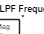

fc=4000;        %cutoff frequency in Hz
wc=2*pi*fc;     %cutoff frequency in rad/s

%modify the code below to create the transfer function
%store transfer function in variable name H
b = 1;
a = [1/wc^2 1/wc 1];
c = [1/wc 1];
H1 = tf(b,a);
H2 = tf(b,c);
H = H1*H2;

%plot the frequency response
freq = logspace(2,4,50);
[mag, phase] = bode(H,2*pi*freq);
mag_dB = 20*log10(abs(mag(:,:)));
figure(1)
clf
semilogx(freq,mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Second Order LPF Frequency Response')
hold on
yyaxis right
semilogx(freq,phase(:,:),'k--')
ylabel('Phase (degrees)')
legend('Mag','Phase')
hold off

## Calculate Component Values for PWM DAC Filter

## 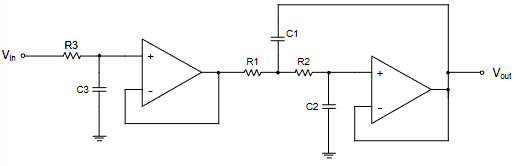

%Show your work for the steps below by inserting some documentation above or below this code block

%Specify the constraint for C2 / C1

%C1 = 4*C2; Which means C2/C1 = 0.25

%Set C1 and C2
C1 = 400*10^-9

C1 = 4.0000e-07

C2 = C1/4

C2 = 1.0000e-07

C3 = 100*10^-9

C3 = 1.0000e-07

%Calculate the values for R1 and R2
%R1 = ((C1/wc)+sqrt((C1/wc)^2 - 4*(C1*C2)* 1/(wc)^2))/(2*C1*C2)
%R2 = 1/(wc^2 * C1 * C2 * R1)
R1 = 200

R1 = 200

R2 = 200

R2 = 200

R3 = 470

R3 = 470

Steps of my work:

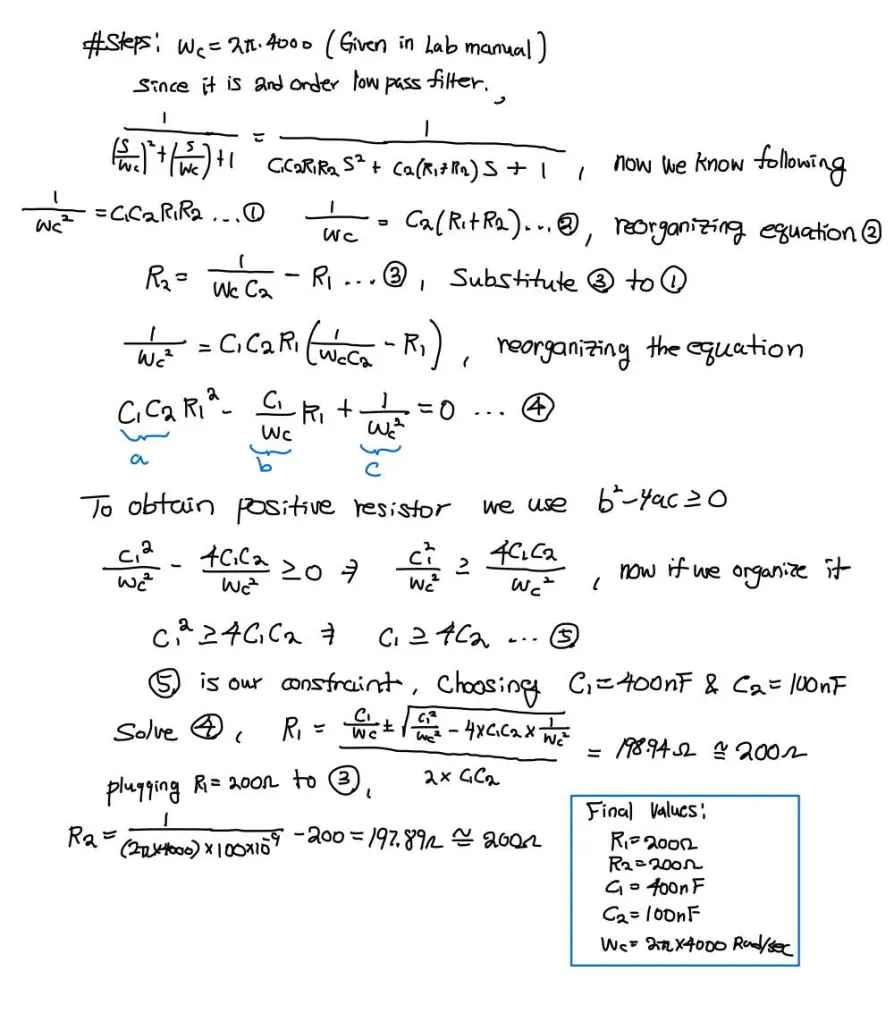

Steps for the extra 1st order section:

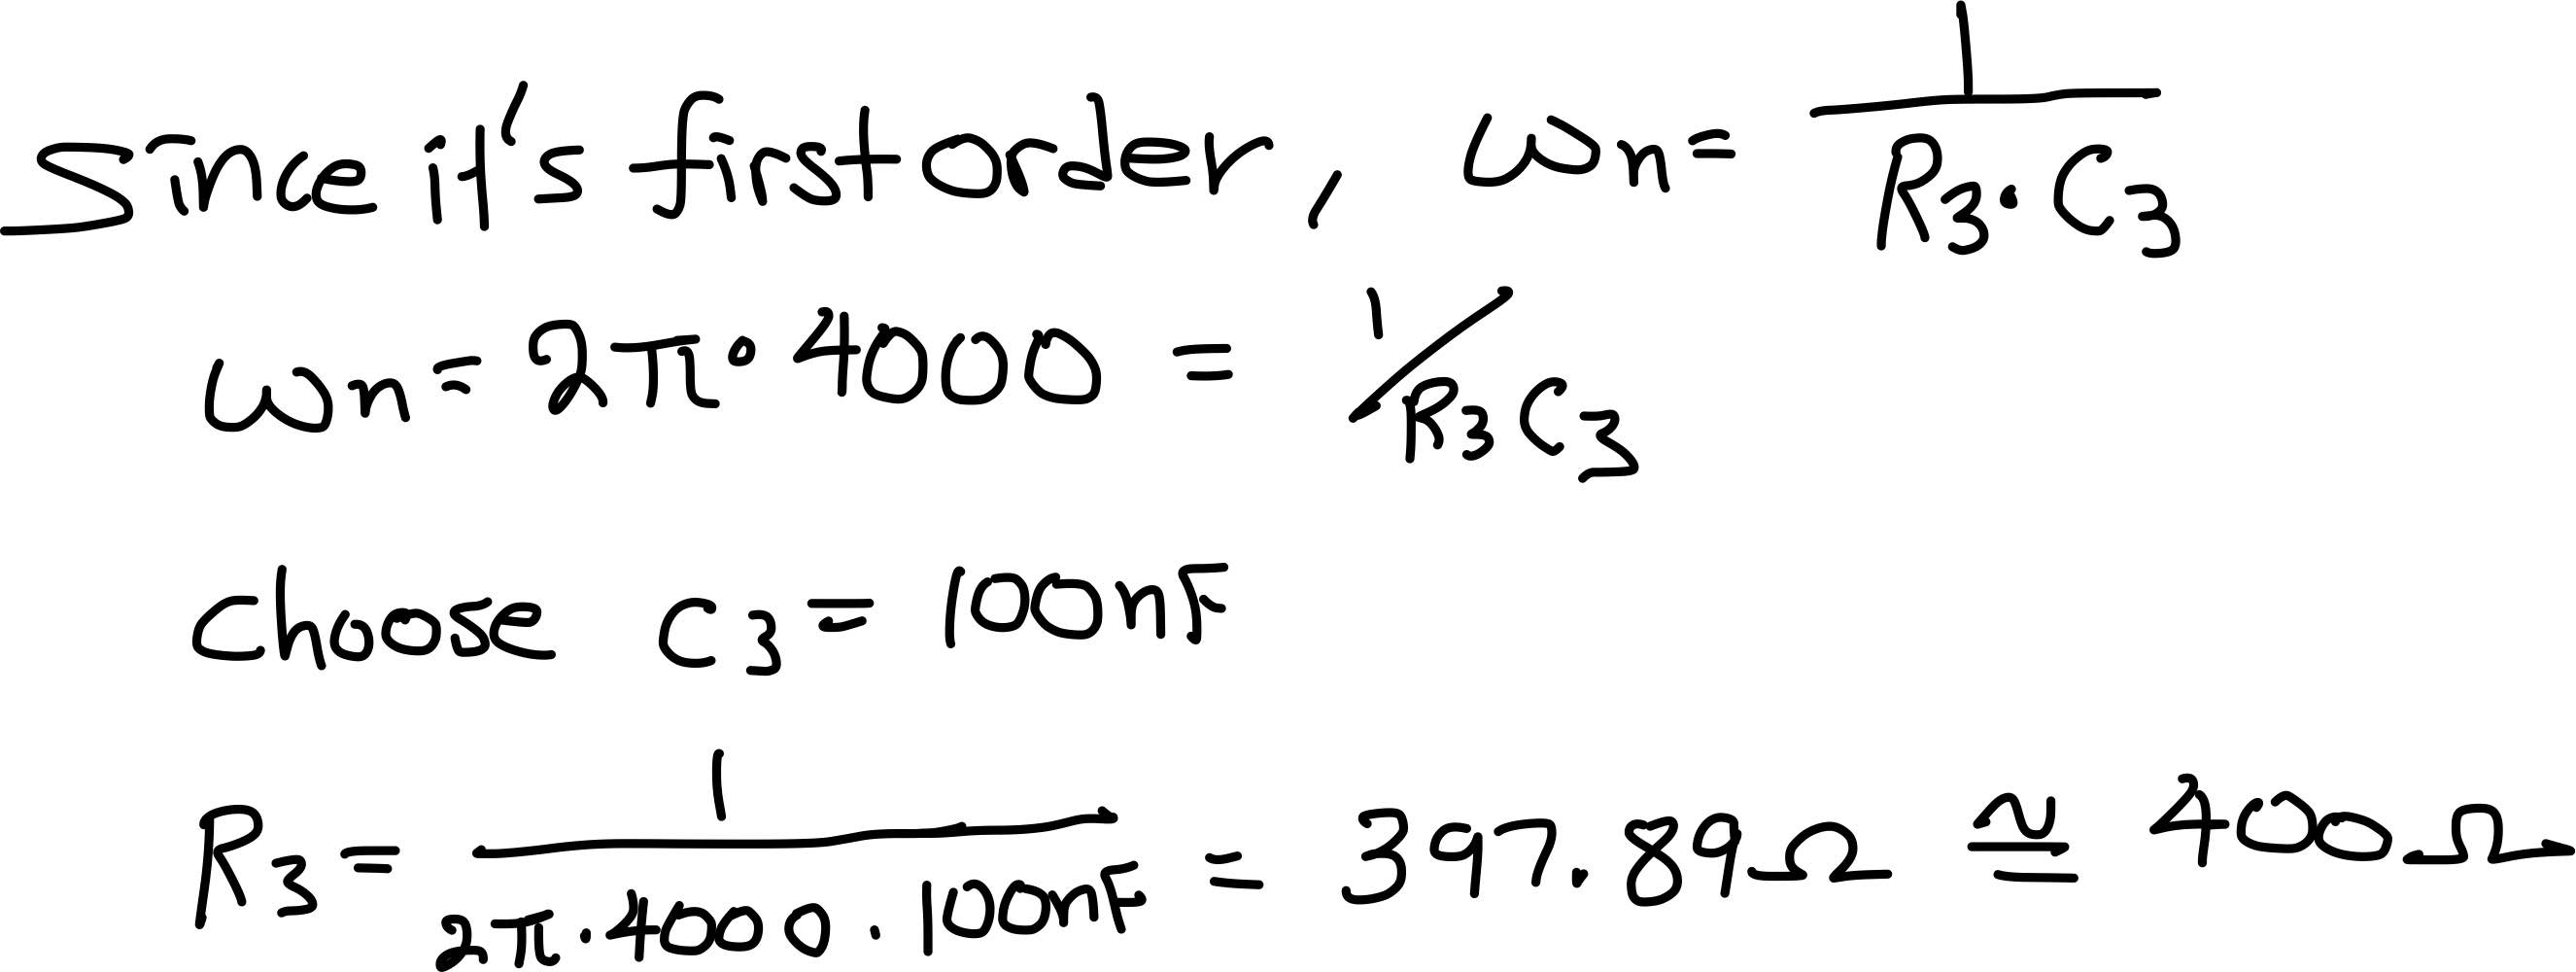

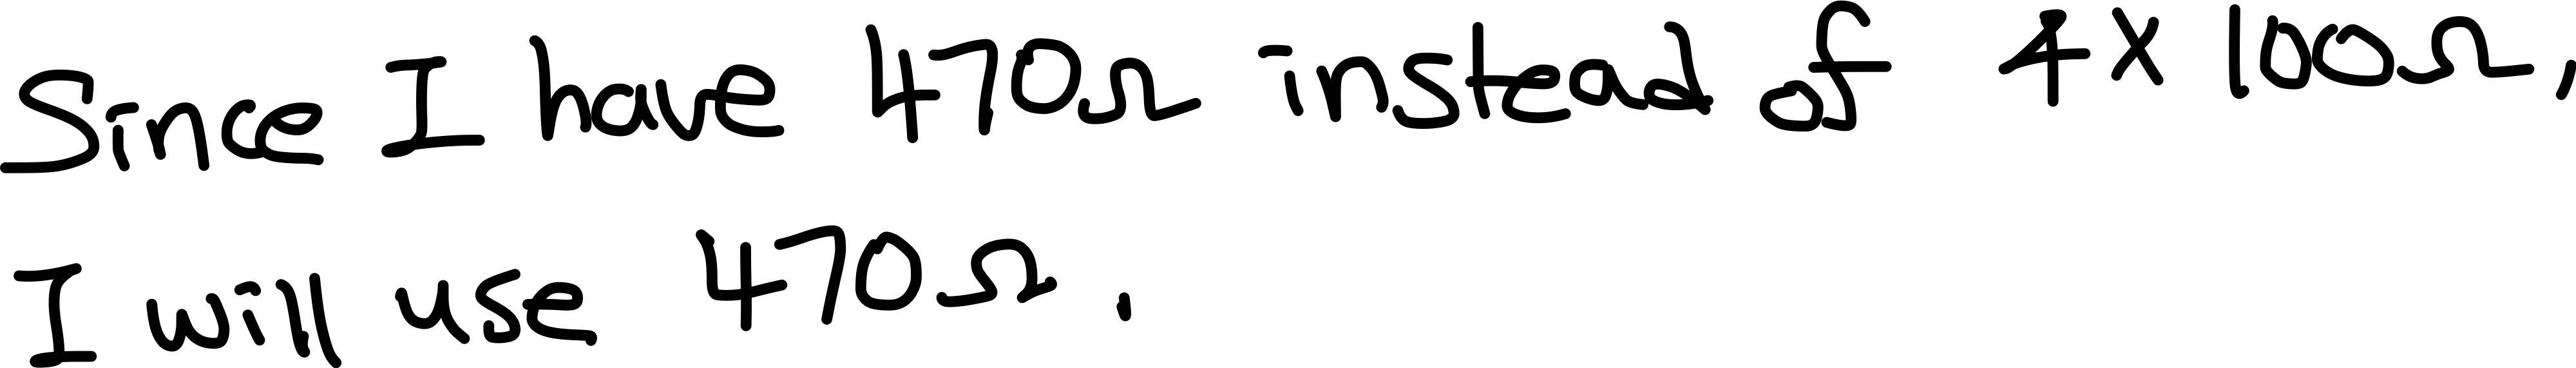

## LTSPICE Schematic

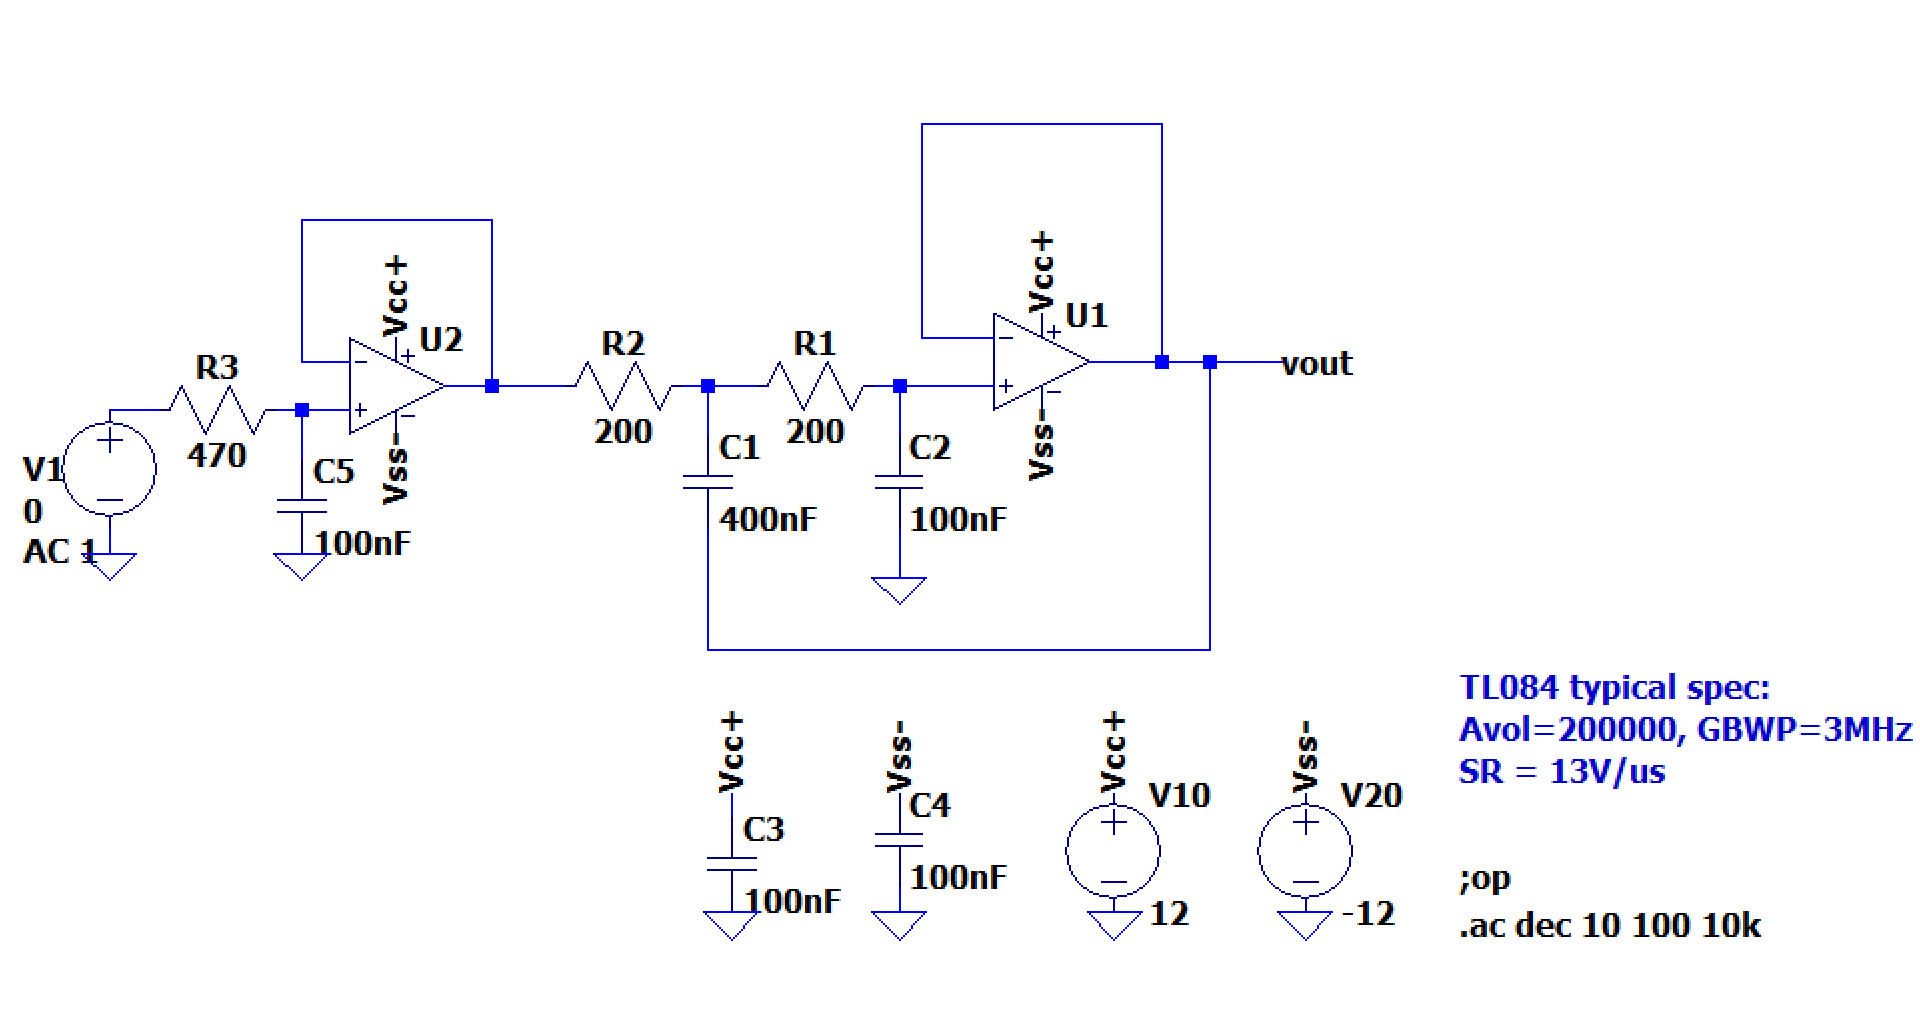

## LTSPICE Simulation Results

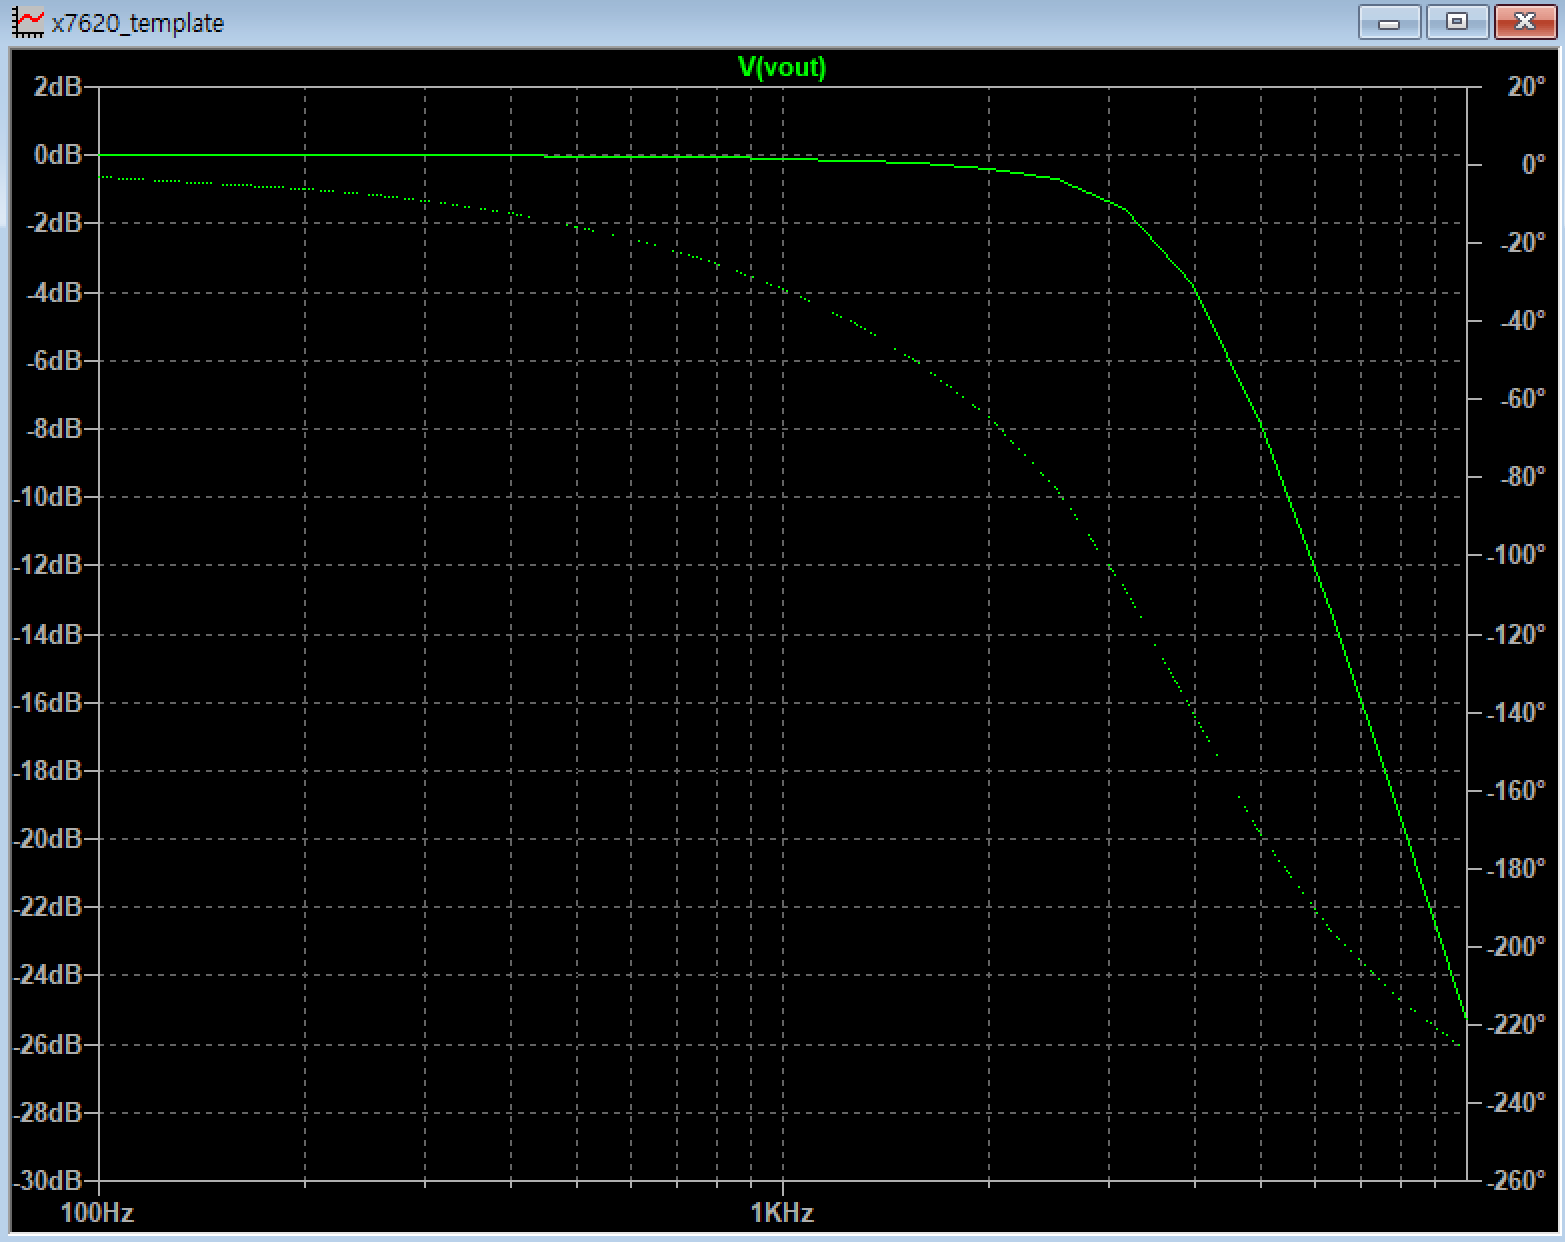

## Measurements

Record your measured data here and compare it against the theoretical results

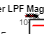

%Measured data; each triplet [f,vout,delay] is 
% f = frequency in Hz
% vout = output voltage, peak to peak
% delay = time delay between input to output, in seconds
measured = [    [2.00e+02, 2.002, 3.30e-05]
                [4.00e+02, 2.013, 3.71e-05]
                [6.00e+02, 2.023, 3.83e-05]
                [1.00e+03, 2.012, 3.95e-05]
                [2.00e+03, 2.155, 4.51e-05]
                [2.50e+03, 2.172, 4.84e-05]
                [3.00e+03, 2.11, 5.25e-05]
                [3.50e+03, 1.964, 5.56e-05]
                [4.00e+03, 1.714, 5.81e-05]
                [4.50e+03, 1.477, 5.91e-05]
                [5.00e+03, 1.241, 5.93e-05]
                [6.00e+03, 8.62e-01, 5.67e-05]
                [7.00e+03, 6.12e-01, 5.31e-05]
                [8.00e+03, 5.06e-01, 4.90e-05]
                [9.00e+03, 3.96e-01, 4.55e-05]

           ];

%Amplitude of input sine wave, peak to peak
%YOU MAY NEED TO ADJUST THIS BASED ON YOUR SETUP
vin = 2;


meas_freq = measured(:,1);
meas_mag_dB = 20*log10(measured(:,2)/vin);
meas_delay = measured(:,3);
meas_phase = (-1)*360*meas_delay.*meas_freq;

figure(2)
clf
semilogx(freq,mag_dB,'r-',meas_freq,meas_mag_dB,'kx')
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Second Order LPF Magnitude Response')
legend('Predicted', 'Measured', 'Location', 'southwest');

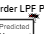


figure(3)
clf
semilogx(freq,phase(:,:),'r-',meas_freq,meas_phase,'kx')
xlabel('Frequency (Hz)')
ylabel('Phase (degrees)')
title('Second Order LPF Phase Response')
legend('Predicted', 'Measured')